# DSP Lab - Homework1

#### Mahdi Mahjouri Namin 40023125

#### Nima Nourizadeh 40023086

close all;
clear;
clc;

**Section 1-1**

In this section, a continuous-time sinusoidal wave is generated using the mathematical equation $x(t) = A \sin(2\pi f t + \varphi)
$ The amplitude (A) is set to 5, the frequency (f) to 1 Hz, and the phase shift (ϕ) to zero. The signal is visualized using both **plot** (for a continuous representation) and **stem** (for a discrete-time representation), demonstrating the difference between continuous and sampled signals.

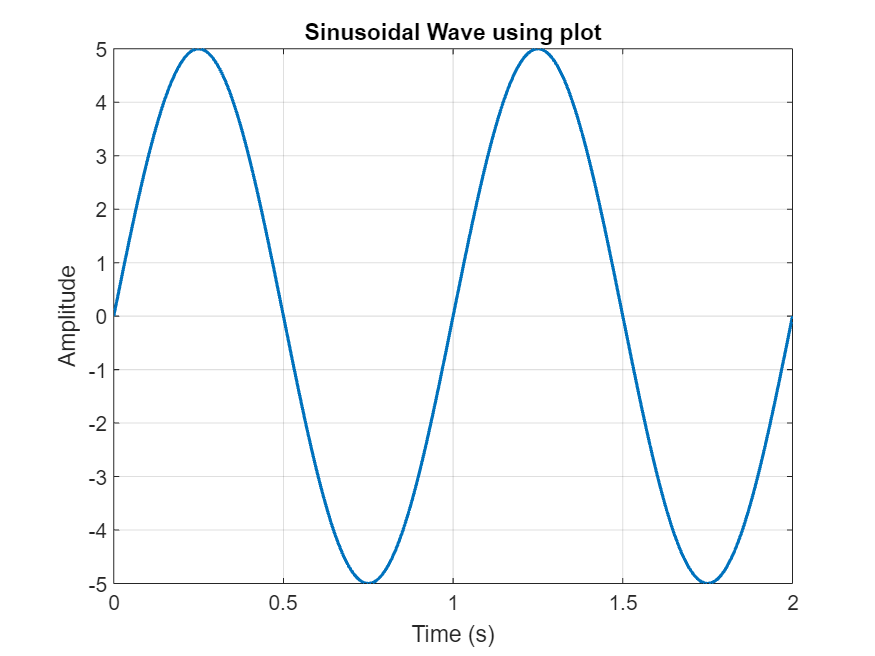

t = 0:0.01:2;
A = 5;
f = 1;
phi = 0;
signal = A*sin(2*pi*f*t + phi);
figure('Name', 'Continuous-Time Sinusoidal Wave');
plot(t, signal, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Sinusoidal Wave using plot');
grid on;

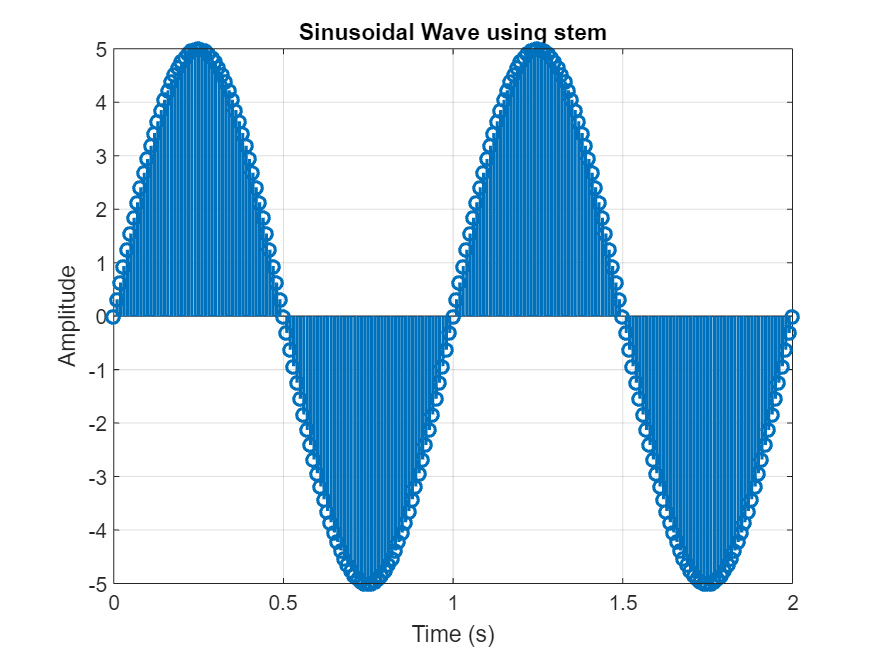

figure('Name', 'Continuous-Time Sinusoidal Wave');
stem(t, signal, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Sinusoidal Wave using stem');
grid on;

**Section 1-2**

To simulate real-world signal distortions, random noise is added to the generated sinusoidal wave. The noise is uniformly distributed in the range [−0.5,0.5]and is summed with the original signal to create a noisy waveform. The effect of noise is analyzed by plotting both the original and noisy signals, allowing for a visual comparison of the distortion introduced by the random fluctuations.

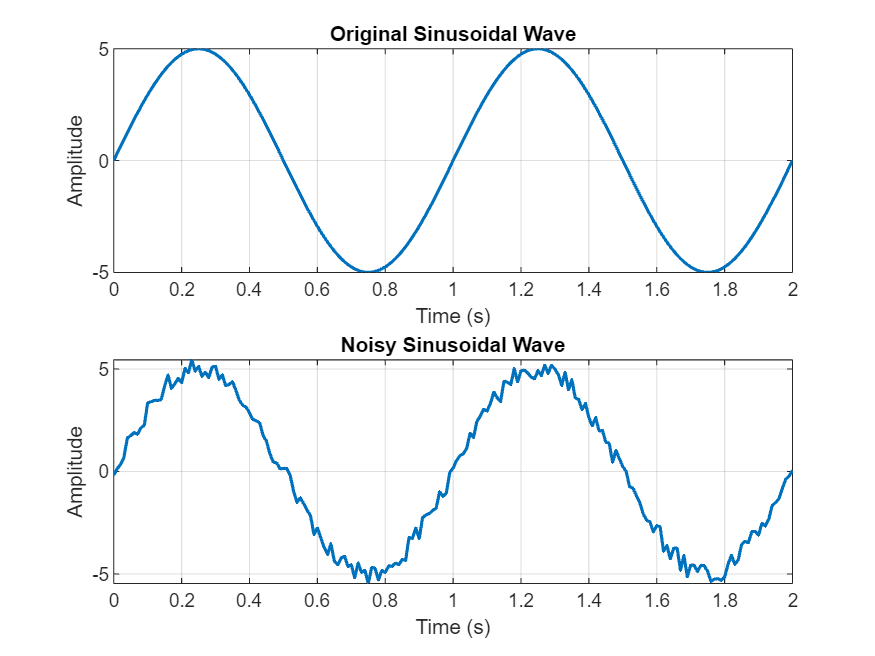

rand_num = rand(1,length(t)) - 0.5;
rand_signal = rand_num + signal;
figure('Name', 'Random Signal');
subplot(211)
plot(t, signal, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Sinusoidal Wave');
grid on;
subplot(212)
plot(t, rand_signal, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Noisy Sinusoidal Wave');
grid on;

**Section 1-3**

A moving average filter is applied to the noisy sinusoidal signal to reduce high-frequency noise and smooth the waveform. The filter is implemented using convolution with a uniform kernel, where the window size determines the level of smoothing. The filtered signal is plotted alongside the noisy signal to illustrate the effectiveness of the moving average filter in noise reduction.

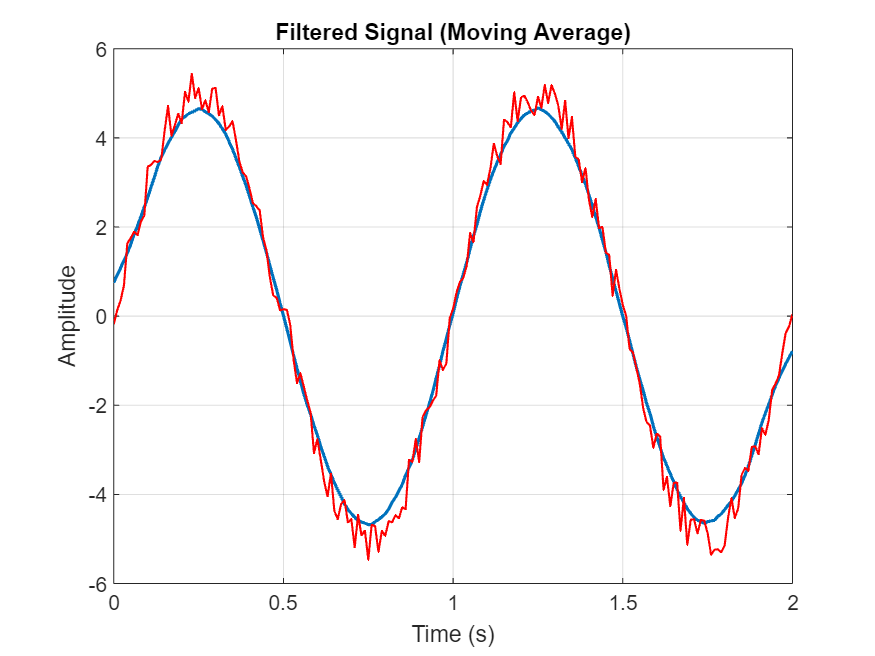

M1 = 0;
M2 = 20;
window_size = M1 + M2 + 1;

kernel = ones(1, window_size) / window_size;
filtered_signal = conv(rand_signal,kernel, "same");

figure('Name', 'Moving Average');
plot(t, filtered_signal, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered Signal (Moving Average)');
grid on;
hold on;
plot(t, rand_signal, 'LineWidth', 1,'Color','r');

**Delay in the Moving Average Kernel (Convolution)****: Centered Window Effect**

- The moving average kernel is a **symmetric** filter, meaning it averages values over a range of past and future samples.

- The kernel size is `window_size = M1 + M2 + 1`, which in this case is 21 samples.

- When you apply convolution with `"same"`, the output is aligned with the center of the kernel.

- Since the kernel extends from `0` (current sample) to `20` (future samples), the **effective delay is**:        $\frac{window\ size - 1 }{2} = \frac{21 - 1}{2}=10 $ samples

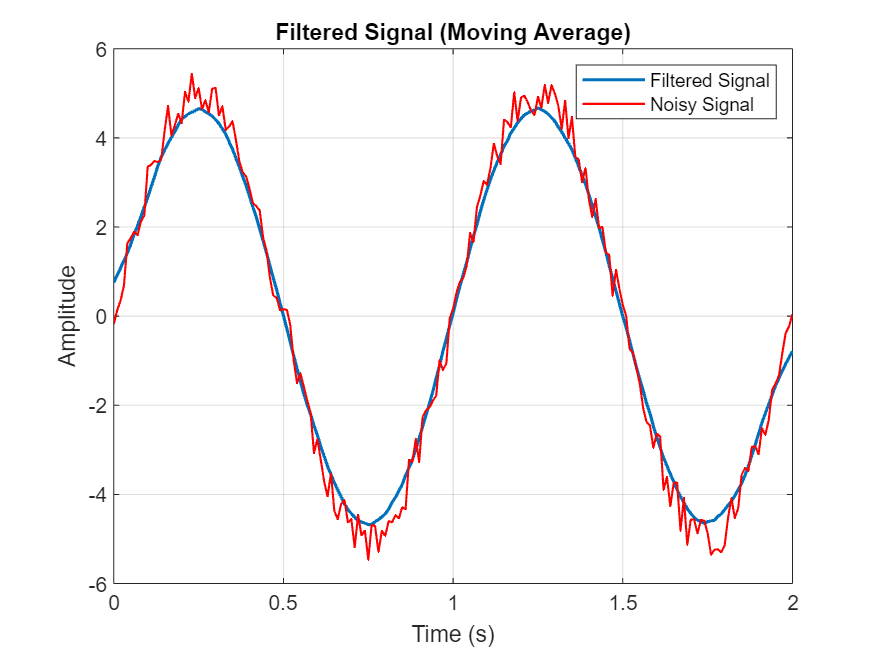

M1 = 10;
M2 = 10;
window_size = M1 + M2 + 1;
kernel = ones(1, window_size) / window_size;
filtered_signal = conv(rand_signal, kernel, "same");
figure('Name', 'Moving Average Filtered Signal');
plot(t, filtered_signal, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered Signal (Moving Average)');
grid on;
hold on;
plot(t, rand_signal, 'LineWidth', 1, 'Color', 'r');
legend('Filtered Signal', 'Noisy Signal');

**Section 1-4**

In this section, the moving average filter is implemented using the `filter` function instead of convolution. This method applies the filter recursively, making it more efficient for real-time processing. The same averaging kernel is used to smooth the noisy signal, and the filtered output is plotted to compare its performance with the previous convolution-based approach.

Both functions perform the same task of smoothing the signal, but the `conv` function with the `"same"` option gives a shorter delay (half the kernel size) compared to `filter`, which has a delay corresponding to the full kernel size. (20 samples delay)

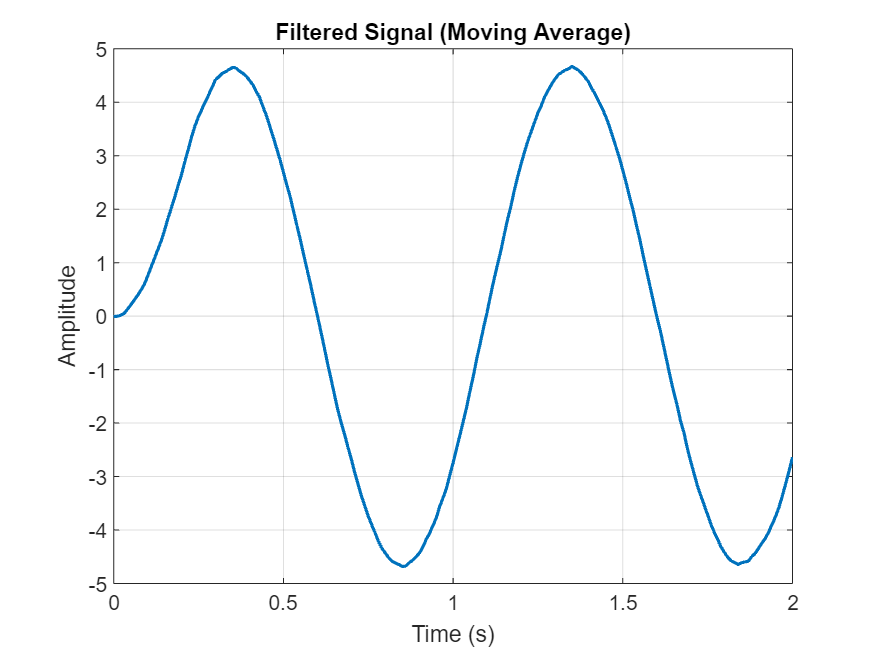

M1 = 0;
M2 = 20;
window_size = M1 + M2 + 1;
kernel = ones(1, window_size) / window_size;
filtered_signal = filter(kernel, 1, rand_signal);

figure('Name', 'Moving Average');
plot(t, filtered_signal, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Filtered Signal (Moving Average)');
grid on;

**Delay in the Filter Kernel (filter function)****: Causal Filtering**

- The `filter` function is implemented as a **causal** filter in MATLAB, meaning it only considers past and present samples.The following difference equation defines a moving-average filter of a vector *x*:        

                                    
$$ y(n)=\frac{1}{windowSize}\left(x(n)+x(n-1)+...+x(n-(windowSize-1))\right). $$


- Since it does **not** use future values (unlike convolution with a symmetric kernel), the output at `n` is computed using past samples, leading to a delay **equal to the full window size minus one.**

**section 1-5**

A discrete-time sinusoidal sequence is generated using a second-order difference equation. This method utilizes a recursive relation where each sample is computed based on previous values, avoiding the need for direct sine function evaluation. The system is implemented using the `filter` function with appropriately chosen coefficients, and the generated sequence is visualized using a stem plot to illustrate its discrete nature.

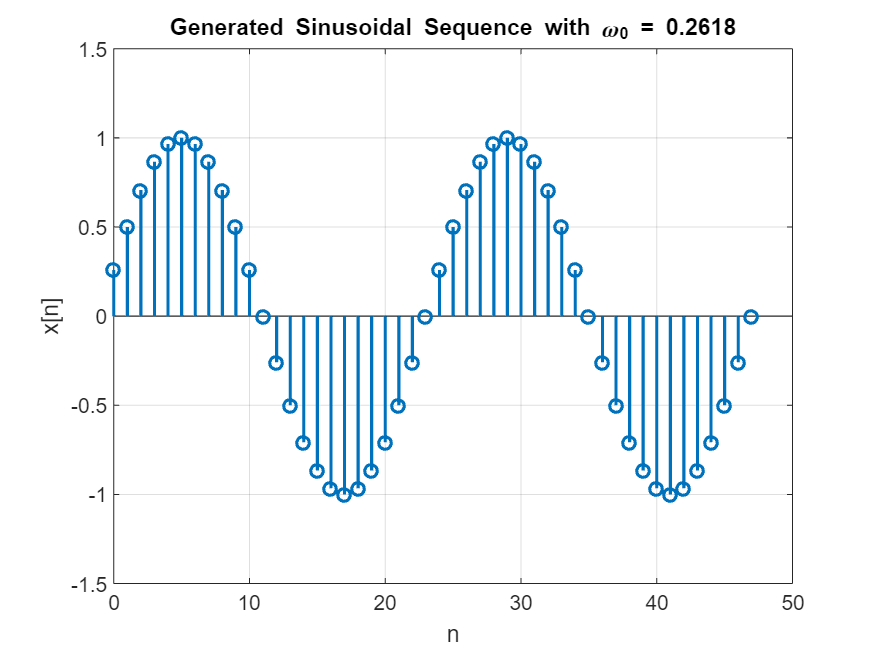

singen(pi/12, 48);

function x = singen(omega0, n)
 
    a = [1, -2*cos(omega0), 1]; % denominator   
    b = [sin(omega0), 0, 0]; % numerator    
   
    u = [1, zeros(1, n-1)]; % Generate Input Signal (unit impulse)   
    x = filter(b, a, u);
    
    figure;
    stem(0:n-1, x, 'LineWidth', 1.5);
    xlabel('n');
    ylabel('x[n]');
    title(['Generated Sinusoidal Sequence with \omega_0 = ', num2str(omega0)]);
    grid on;
end


